% Program for finding a good fit for the values of the RGB color sensor.

T = readtable('data_calibration_v2.csv');

colors = T{:, 1}

colors =            0
          51
         102
         153
         204
         255
       51000
       51051
       51102
       51153


reading1 = T{:, 2};
reading2 = T{:, 3};
reading3 = T{:, 4};

average = (reading1 + reading2 + reading3)/3;

plot(colors, reading1, '*r')
%plot(colors, reading2, '*b')
%plot(colors, reading3, '*g')

xlim([0 255255256])

 [colorFit,gof] = fit(colors,reading1, 'cubicspline') 

colorFit =      Cubic interpolating spline:
       colorFit(x) = piecewise polynomial computed from p
     Coefficients:
       p = coefficient structure

gof = struct with fields:
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


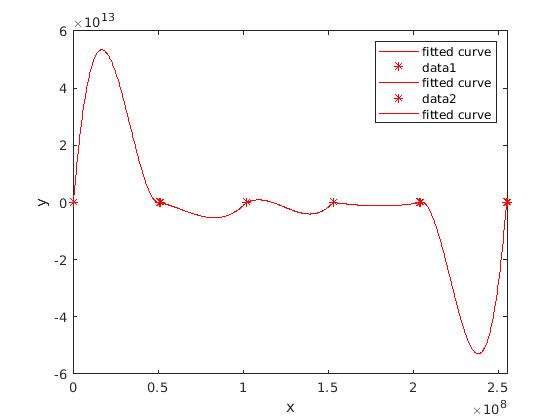

 hold on
 plot(colorFit)


 [colorFit2,gof] = fit(colors,reading2, 'poly1') ;
 [colorFit3,gof] = fit(colors,reading3, 'poly1') ;

 [colorFit4, gof] = fit(colors, average, 'poly1')

colorFit4 =      Linear model Poly1:
     colorFit4(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1506  (0.04691, 0.2542)
       p2 =   1.031e+08  (8.704e+07, 1.191e+08)

gof = struct with fields:
           sse: 9.6993e+17
       rsquare: 0.0369
           dfe: 214
    adjrsquare: 0.0324
          rmse: 6.7323e+07
